% generate random pulses to compare with the BER
close all;
clear all;
clc;

num = 1e4;
s = randi([0 1],1,num); % is it the correct signal? which signal should i simulate, analogic(stepfunc) or digital(impulse func)?
% digital signal-interpolate-analogic signal-awgn-conv-sample-threshold-ber
t = linspace(1,num,num);

P_d = length(find(s==0))./num % verify P(0)=P(1)=0.5

P_d = 0.5065

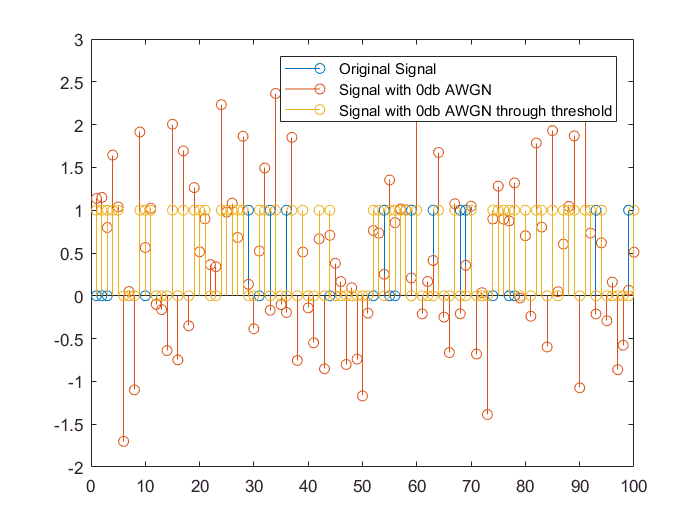

% %{
figure;
stem(t, s);
hold on;
%}

SNR = 0;
s1 = awgn(s,SNR,'measured'); % E_s/N_0 = E_b/N_0 + 10log10(k) = 0db (k = 1,E_b/N_0 = 0)
% %{
stem(t, s1);
hold on;
%}
s1_1 = zeros(size(s1));
s1_1(s1>=0.5) = 1; % page144 3.32 threshold=(a1+a2)/2
% %{
stem(t, s1_1);
legend('Original Signal',...
    ['Signal with ',num2str(SNR),'db AWGN'],...
    ['Signal with ',num2str(SNR),'db AWGN through threshold']);
xlim([0 100]);
hold off;

%}
BER_0 = length(find(s1_1-s))./num % BER of Signal with 0db AWGN

BER_0 = 0.2323

BER = qfunc(sqrt(10.^(SNR/10)))

BER = 0.1587

return

s2 = awgn(s,2,'measured');
%{
figure;
stem(t, s);
hold on;
stem(t, s2);
legend('Original Signal','Signal with 2db AWGN');
hold off;
%}
s2_1 = zeros(size(s));
s2_1(s2>=0.5) = 1;
%{
figure;
stem(t, s);
hold on;
stem(t, s2_1);
legend('Original Signal','Signal with 2db AWGN through threshold');
hold off;
%}
BER_2 = length(find(s2_1-s))./num % BER of Signal with 2db AWGN

s10 = awgn(s,10,'measured');
%{
figure;
stem(t, s);
hold on;
stem(t, s10);
legend('Original Signal','Signal with 10db AWGN');
hold off;
%}
s10_1 = zeros(size(s));
s10_1(s10>=0.5) = 1;
%{
figure;
stem(t, s);
hold on;
stem(t, s10_1);
legend('Original Signal','Signal with 10db AWGN through threshold');
hold off;
%}
BER_10 = length(find(s10_1-s))./num % BER of Signal with 10db AWGN





EbN0_db = linspace(0,10,num);
EbN0 = 10.^(EbN0_db/10);
% BER = 0.5.*erfc(sqrt(EbN0));
BER = qfunc(sqrt(EbN0)); % rho = 0
% %{
figure;
semilogy(EbN0_db, BER);
hold on;
plot(0,BER_0,'r*');
hold on;
plot(2,BER_2,'r*');
hold on;
plot(10,BER_10,'r*');




grid on;
ylabel('BER');
xlabel('E_b/N_0 (dB)');
legend('analytical expression for BER');
hold off;
%}

